clc
clear

load (".\DataAndVariables\BaseDefinitions.mat")

% to convert the line admitances from rectangular to polar form
[theta, rho] = cart2pol(real(Y), imag(Y));
% theta = angle
% rho = magnitude

pqBus = 2:15;
nrPQ = length(pqBus);

delta = zeros(nrBus, 1); % voltage phase angle (initialise to slack bus, if possible)
V = ones(nrBus, 1); % voltage magnitude (initialise to slack bus, if possible)

Pcal = zeros(nrBus,1);
Qcal = zeros(nrBus,1);

J1 = zeros(nrBus-1);
J2 = zeros(nrBus-1, nrPQ);
J3 = zeros(nrPQ, nrBus-1);
J4 = zeros(nrPQ);

Vout = zeros(15,96);
deltaOut = zeros(15,96);
itrOut = zeros(15,1);

tic
for k=1:length(Psch)
    tolerance=1; 
    iteration = 0;
    delta = zeros(nrBus, 1);
    V = ones(nrBus, 1);

    while (tolerance > 1e-3)
    % calculation of powers for pq buses
        for i = 1:nrPQ
            m = pqBus(i); % PQ bus indexes, so equation includes only PQ buses
            Pcal(m) = V(m)*sum(rho(m,:).*V.'.*cos(theta(m,:)-delta(m)+delta.'));
            Qcal(m) = -V(m)*sum(rho(m,:).*V.'.*sin(theta(m,:)-delta(m)+delta.'));
        end
        
        % calculation of mismatches
        dP = Psch(2:nrBus,k) - Pcal(2:nrBus);
        dQ = Qsch(2:nrBus,k) - Qcal(2:nrBus);
        % mismatch vector
        mismatch = [dP ; dQ];
        
        % calculation of jacobian matrices
        for i = 1:nrBus-1
            m = i+1; % +1 as to exclude slack bus
            for j = 1:nrBus-1
                n = j+1;
                if i == j % diagonal elements for J1
                    % subtraction after sum, due to j = i excluded
                    YVsum = sum(rho(m,:).*V.'.*sin(theta(m,:)-delta(m)+delta.')) ...
                        -rho(m,m)*V(m)*sin(theta(m,m));
                    %deltas ommited in last term, due to delta(m)-delta(m)=0
                    J1(i,i) = V(m)*YVsum;
                else % off-diagonal elements for J1
                    J1(i,j) = -rho(m,n)*V(m)*V(n)*sin(theta(m,n) ...
                        -delta(m)+delta(n));
                end 
            end
        end
        
        for i = 1:nrBus-1
            m = i+1;
            for j = 1:nrPQ
                n = pqBus(j); % PQ bus indexes, so equation includes only PQ buses
                if i == j % diagonal elements for J2
                    YVsum = sum(rho(m,:).*V.'.*cos(theta(m,:)-delta(m)+delta.')) ...
                        -rho(m,m)*V(m)*cos(theta(m,m));
                    J2(i,i) = 2*rho(m,m)*V(m)*cos(theta(m,m))+YVsum;
                else % off-diagonal elements for J2
                    J2(i,j) = rho(m,n)*V(m)*cos(theta(m,n)-delta(m)+delta(n));
                end 
            end
        end
        
        for i = 1:nrPQ
            m = pqBus(i);
            for j = 1:nrBus-1
                n = j+1;
                if i == j % diagonal elements for J3
                    YVsum = sum(rho(m,:).*V.'.*cos(theta(m,:)-delta(m)+delta.')) ...
                        -rho(m,m)*V(m)*cos(theta(m,m));
                    J3(i,i) = V(m)*YVsum;
                else % off-diagonal elements for J3
                    J3(i,j) = -rho(m,n)*V(m)*V(n)*cos(theta(m,n) ...
                        -delta(m)+delta(n));
                end 
            end
        end
        
        for i = 1:nrPQ
            m = pqBus(i);
            for j = 1:nrPQ
                n = pqBus(j);
                if i == j % diagonal elements for J4
                    YVsum = sum(rho(m,:).*V.'.*sin(theta(m,:)-delta(m)+delta.')) ...
                        -rho(m,m)*V(m)*sin(theta(m,m));
                    J4(i,i) = -2*rho(m,m)*V(m)*sin(theta(m,m))-YVsum;
                else % off-diagonal elements for J4
                    J4(i,j) = -rho(m,n)*V(m)*sin(theta(m,n)-delta(m)+delta(n));
                end 
            end
        end
        
        % initialize jacobian
        J = [J1 J2; J3 J4];
        
        % create sensitivity matrix
        sensitivity = inv(J);

        % calculate correction vector
        correction = J\mismatch;
        
        delta(2:nrBus) = delta(2:nrBus) + correction(1:nrBus-1);
        V(2:nrBus) = V(2:nrBus) + correction(nrBus:end);
        
        iteration=iteration+1;
        tolerance = max(abs(mismatch));
    end
    Vout(:,k) = V;
    deltaOut(:,k) = delta;
    itrOut(k) = iteration;
    sensQ = sensitivity(nrBus:end,nrBus:end);
end
toc

Elapsed time is 0.154260 seconds.


mean(itrOut)

ans = 3.5833

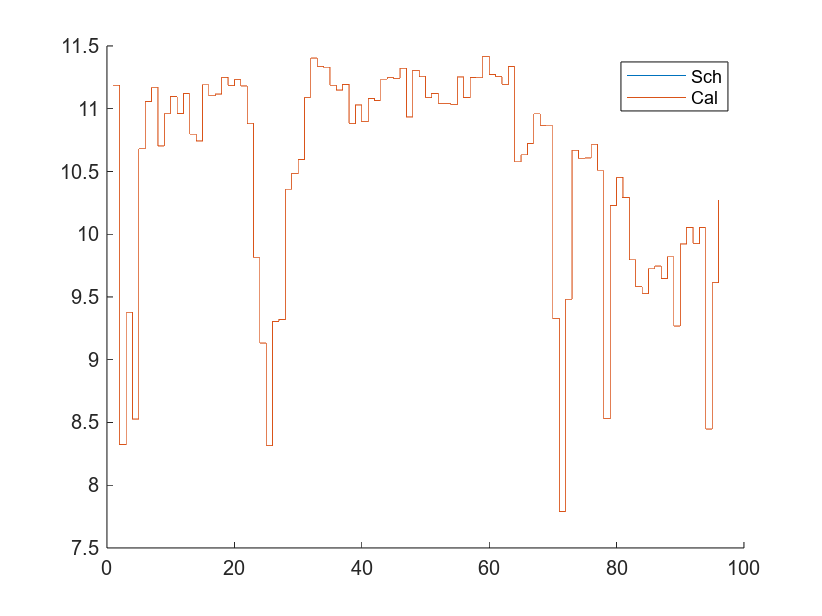


[x,y] = pol2cart(deltaOut,Vout);

Vtest = complex(x,y);

Pout = real(conj(Vtest).*(Y*Vtest));
Qout = -imag(conj(Vtest).*(Y*Vtest));

figure
hold on
stairs(Psch(2,:))
stairs(Pout(2,:))
legend("Sch", "Cal")
hold off

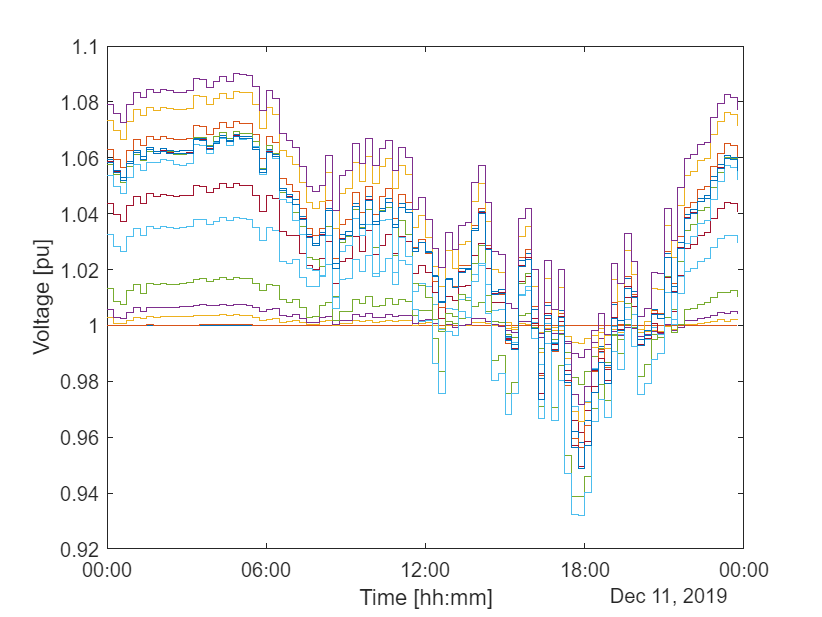


figure
stairs(timestamp,Vout.')
ylabel("Voltage [pu]")
xlabel("Time [hh:mm]")
set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPosition', [0 0 16 9]);
saveas(gcf,'Figure/Newton-Raphson-V','epsc')

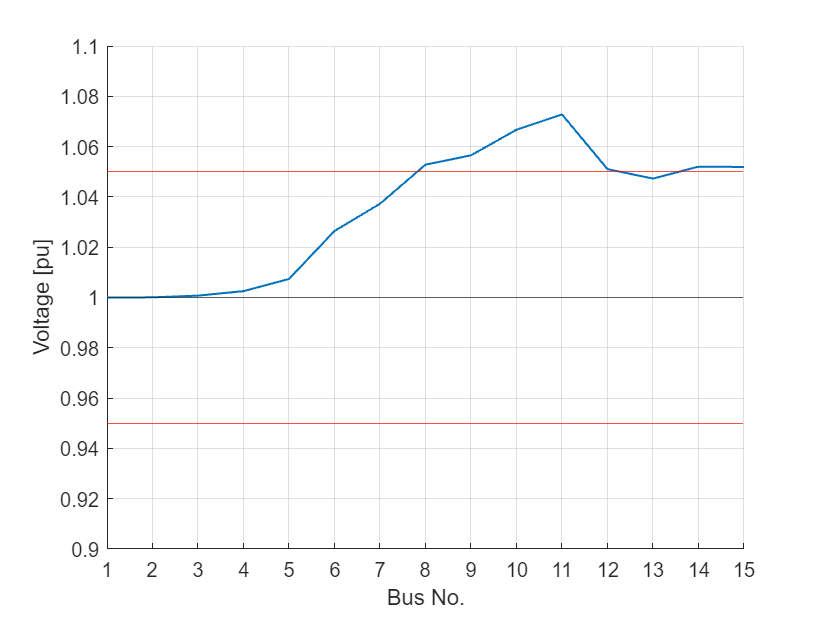


figure
hold on
plot(Vout(:,3), LineWidth=1)
grid on
ylabel("Voltage [pu]")
xlabel("Bus No.")
xticks(linspace(1,15,15))
ylim([0.9 1.1])
xlim([1 15])

yline(1)
yline([1.05 0.95],Color='red')
hold off
set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPosition', [0 0 16 9]);
saveas(gcf,'Figure/bus_Voltage_Setponit','epsc')

Mean values

Vm0 = mean(Vout,2);
d0 = mean(delta,2);
V0 = [d0(2:end) ; Vm0(2:end)]

V0 =     0.0008
    0.0021
    0.0035
    0.0070
    0.0138
    0.0176
    0.0230
    0.0244
    0.0264
    0.0274


P0 = mean(Psch,2);
Q0 = mean(Qsch,2);
S0 = [P0(2:end) ; Q0(2:end)]

S0 =    10.5339
   -1.5726
   -0.6629
   -1.3889
   -0.5582
   -0.4697
    5.4712
   -0.8595
   -1.1456
    6.4864



% save("AvgValues", "V0","S0");